# Riemann Sums

[⇦ Overview](matlab: OpenOverview)

One of the most important and useful concepts of calculus is the idea of computing accumulation. In many situations, there is information about a rate of change (e.g., acceleration, velocity, concentration, flow, power) and calculus presents tools for calculating the accumulation that occurs (e.g., velocity, position, amount, volume, energy, etc.). 

## Calculating Solar Energy Generation

### Background

Consider the power generated by a fixed solar array with a maximum rated output of 643.545 kW. To convert this power (in kilowatts) into energy (kilowatt-hours) requires accumulating this power over time. 

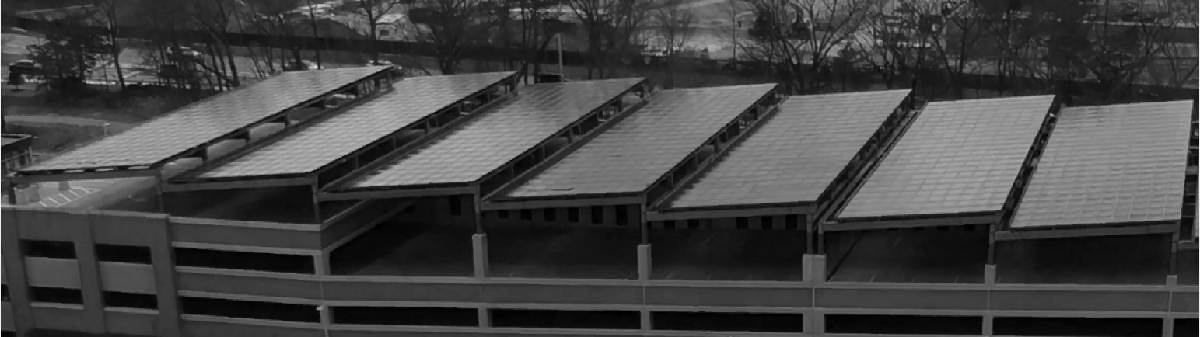

Data from the MathWorks Lakeside Campus parking garage solar array, March 14-20, 2021. 

figure;           % Initialize a figure

% Load solar power generation data and preprocess to track time
data = readtable("SolarPowerGeneration.csv");
data.Timestamp(1);
data.Timestamp = data.Timestamp-data.Timestamp(1);

% Plot the data and label the graph and axes
plot(datenum(data.Timestamp), data.AC_kw)
title("Power Generation, March 14-20 2021")
xticks(.5:1:6.5)
xticklabels(["Day 1" "Day 2" "Day 3" "Day 4" "Day 5" "Day 6" "Day 7"])
xlabel("Time since 00:00, March 14, 2021 (days)")
ylabel("Power in kilowatts (kw)")
 

#### Select a day

Choose a day to analyze more carefully.

desiredDay = 3;              
% Use a try/catch block to fail gracefully if the sections are run out of
% order. Alternately, this could include live controls that run this
% section and any modified or not yet run sections above
try 
    [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(desiredDay,data);   % Check if the data is loaded
catch
    % If the data set is not yet loaded, do so here
    disp("You must load the data before you can analyze it.")
    disp("Loading data now ... to plot the full dataset, click the 'Load and Plot Data' button, above.")
    data = readtable("SolarPowerGeneration.csv");
    data.Timestamp(1);
    data.Timestamp = data.Timestamp-data.Timestamp(1);
    disp("Data loaded, proceeding with analysis...")
    [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(desiredDay,data);
end

% Plot the selected data for the single day and label the graph and axes
% Include a special note for the exceptionally short day due to the time
% change to EDT from EST on March 14, 2021
figure;
plot(dataHours,dataPower)
title("Power Generation on "+strDay+", March "+dateDay+", 2021")
if desiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

Focus on the period when it wasn't dark, so the panels had a chance of generating electricity.

% Eliminate the leading and trailing 0's by restricting to times
% approximating sunrise and sunset
figure;
p1 = plot(dataHours(sunrise:sunset),dataPower(sunrise:sunset));
xlim([6+2/3 19+1/12])
title("Power Generation on "+strDay+", March "+dateDay+", 2021")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

### Continuity of Datasets

This graph looks continuous, but in fact it is linearly interpolated between each adjacent datapoint, generated by sensor reports every minute across the day. Consider the scatterplot representation:

% Plot the data as discrete points to observe the scatter values
figure;
p2 = plot(dataHours(sunrise:sunset),dataPower(sunrise:sunset),".","MarkerSize",9);
xlim([6+2/3 19+1/12])
title("Data points in Power Generation on "+strDay+", March "+dateDay+", 2021")
if desiredDay == 1
    subtitle("Note the 23 hour day because of the time zone change")
end
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")

 **Reflect**

- How easy is it to fit a simple curve to this data? Does it matter which day of the week is chosen?

- Are most real-world datasets continuous or discrete? Why? What implications does this have for using calculus in applications?

- Is the underlying data in this situation, where solar panels are generating power, continuous or discrete?

## Application: Riemann Sums with Rectangular Approximations

This data provides sensor readings at one minute time slices across the entire day. To calculate an approximation of the amount of energy generated, it is necessary to add up an approximation of the power generated in each time slice by the length of the time slice. Visually, if we select a left-endpoint approximation:

% Check to see if the data is loaded in the workspace, and if not load it 
% for a default day of Tuesday, March 16, 2021, without displaying errors
if ~exist("sunrise","var")              % If a day is not chosen, use desiredday = 3 by default
    try
        [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(3,data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
        rootDir = fileparts(mfilename('fullpath'))
        data = readtable("SolarPowerGeneration.csv");
        data.Timestamp(1);
        data.Timestamp = data.Timestamp-data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(3,data);
    end
end

% Initialize parameters
energy = 0;     % generated energy (kWh)      
dt = 1/60;      % minimal data step size (hours)
end0 = length(dataHours(sunrise:sunset));
% Set up the interval length in multiples of the minimal step size
skip = 60;
% Select the Riemann sum method of value approximation
endPt = "left";     
% Graph the output approximation overlaid on the data
figure
plot(dataHours(sunrise:sunset),dataPower(sunrise:sunset));
hold on
plot(dataHours(sunrise:skip:sunset),dataPower(sunrise:skip:sunset),"o")
for k = sunrise:skip:sunset
    xval = dataHours(k);
    if endPt == "midpoint"
        if mod(skip,2)==1
            % If the data is known at the midpoint of the interval, use it
            height = dataPower(k+(skip+1)/2);
        else
            % If the data is not known, use linear interpolation to
            % estimate an appropriate value between the two nearest points
            height = mean([dataPower(k+skip/2) dataPower(k+skip/2+1)]);
        end
    elseif endPt == "left"
        % Select the left endpoint of the interval 
        height = dataPower(k);
    elseif endPt == "right"
        % Select the right endpoint of the interval
        height = dataPower(k+skip);
    end
    % Draw the rectangle on the plot
    rectangle("Position",[xval 0 skip*dt height],"EdgeColor","r");
    % Add the approximated energy generated in this interval to the total
    energy = energy+skip*dt*height;
end
if endPt == "midpoint"
    % Add black stars marking the midpoint values of each interval
    desiredPts = sunrise:skip:sunset-skip;
    if mod(skip,2) == 1
        % If the data is known at the midpoint of the interval, use it
        plot(dataHours(desiredPts)+(skip/2)*dt,dataPower(desiredPts+(skip+1)/2),"k*","MarkerSize",8)
    elseif mod(skip,2) == 0
        % If the data is not known, use linear interpolation to
        % estimate an appropriate value between the two nearest points
        plot(dataHours(desiredPts)+(skip/2)*dt,(dataPower(desiredPts+skip/2)...
            +dataPower(desiredPts+skip/2+1))/2,"k*","MarkerSize",8)
    end
end
title("Energy Generation on "+strDay+", March "+dateDay+", 2021")
subtitle("Estimated energy generated = "+energy+"kwh, "+endPt+" approximation")
xlabel("Hours since midnight (hr)")
ylabel("Power (kw)")
hold off

Notice that many of these rectangles are overestimating (or underestimating) the value of the energy generated over that slice of time. 

  **Try**. By default, this plot is generated with a step size of 1 hour (60 minutes) and uses the left-endpoint to approximate the power generated over the entire interval. Try selecting both the right-endpoint approximation and the midpoint approximation as well as shortening the step size.

 **Reflect**.

- Which method (left-endpoint, right-endpoint, or midpoint) generates the most accurate approximation to the total energy generated?

- What impact does shortening the step size have on the total energy estimate? Does it matter whether it is using a left-endpoint, right-endpoint, or midpoint approximation?

#### Visualizing Error in Riemann Sum Approximations

Visualizing the error at each step requires tracking how much over-estimation and under-estimation contributes to each estimate. The red area visualizes the overestimation of energy production, while green area visualizes the underestimation of energy production.

% Check to see if the data is loaded in the workspace, and if not load it 
% for a default day of Tuesday, March 16, 2021, without displaying errors
if ~exist("sunrise","var")              % If a day is not chosen, use desiredday = 3 by default
    try
        [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(3,data);
    catch
        disp("You must load the data before you can analyze it.")
        disp("Loading data now ... to plot the full dataset, return to the beginning of the file.")
        data = readtable("SolarPowerGeneration.csv");
        data.Timestamp(1);
        data.Timestamp = data.Timestamp-data.Timestamp(1);
        disp("Data loaded, proceeding with analysis on Tuesday, March 16, 2021...")
        [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(3,data);
    end
end
dt = 1/60;   % minimal data step size (hours)

% Select the method of Riemann sum approximation
endPt = "Left";   
minskip = 1;
for skip=60:-1:minskip
    % Create 60 plots as individual frames showing how decreasing the step
    % size of "skip" impacts the estimate of the energy generated
    energy = 0;
    plot(dataHours(sunrise:sunset),dataPower(sunrise:sunset));
    hold on
    for k = sunrise:skip:sunset
        xval = dataHours(k);
        if endPt == "Midpoint"
            if mod(skip,2)==1
                % Choose the midpoint value, if known
                height = dataPower(k+(skip+1)/2);
            else
                % Interpolate the midpoint value between adjacent known
                % values
                height = mean([dataPower(k+skip/2) dataPower(k+skip/2+1)]);
            end
        elseif endPt == "Left"
            % Select the left endpoint value for the interval
            height = dataPower(k);
        elseif endPt == "Right"
            % Select the right endpoint value for the interval
            height = dataPower(k+skip);
        elseif endPt == "Maximum"
            % Select the maximum known value over the interval
            height = max(dataPower(k:k+skip));
        elseif endPt == "Minimum"
            % Select the minimum known value over the interval
            height = min(dataPower(k:k+skip));
        end
        % Plot the rectangular approximation 
        rectangle("Position",[xval 0 skip*dt height],"EdgeColor","k");
        energy = energy+skip*dt*height;
        % Plot the over- or under-estimate in different colors
        viewRiemannBetween(dataHours(k:k+skip),dataPower(k:k+skip),height)
    end
    title("Estimated Energy Generation of "+energy+" kwh on "+strDay+", March "+dateDay+", 2021")
    subtitle(endPt+" endpoint approximation, step = "+skip+" minutes")
    xlabel("Hours since midnight (hr)")
    ylabel("Power (kw)")
    hold off
    waitTime = 0.2;
    pause(waitTime);
    drawnow
end

  **Try**.

- Change the method of approximation to right endpoint, midpoint, maximum value, and minimum value.

- Change the day of the week that you are studying.

- Use the slider or watch the animation to observe the impact of increasing/decreasing the step size.

 **Reflect**.

- What do you notice about the error for the different approximation methods? 

- What impact does shortening the step size have on the total energy estimate? Does it matter which type of estimate you are using? Why or why not?

## Riemann Sum with Trapezoidal Approximation

Constant value approximations are frequently clearly bad approximations, even to the naked eye. Continuing the theme of approximating functions by polynomials, after a constant (0th degree polynomial) the 1st degree polynomial approximation is a line. Using the endpoints of each interval this gives us a trapezoidal approximation of the area under the curve.

syms x
f(x) =  (x-5)*(x+2)*(x-7);
stepsize = 188; 
xVals = -5:.01:5;
fVals = f(xVals);
plot(xVals,fVals)
% fplot(f(x),[1 10],"k-","LineWidth",2)
hold on
sumTot = displayTrapezoidMethod(xVals,fVals,1,length(xVals),stepsize,.01);
title("Trapezoidal Method with step size "+stepsize*(xVals(2)-xVals(1)))
subtitle("")
hold off


### Application: Solar Energy Data

Compare using trapezoidal approximation on the solar energy data with different step sizes to the best possible estimate given the resolution of the data.

 
% Compute and display the energy with varying step sizes from 1 hour down
% to 5 minutes using the trapezoidal approximation
energy = displayTrapezoidMethod(dataHours,dataPower,sunrise,sunset,60:-5:5,1/60);
% Compute the best available energy estimate given the data
height = (dataPower(sunrise+1:sunset)+dataPower(sunrise:sunset-1))/2;
energy = [energy;sum(height*(1/60))];
% Create a new plot of the estimates of energy generation against step size
plot([60:-5:5 1],energy)
hold on
% Add a line for the best estimate
yline(energy(end),"r:")
title("Energy Generation Estimates compared to best")
xlabel("Step size (min)")
ylabel("Energy (kwh)")
legend(["Energy Estimate","Best Approximation"],"Location","northwest")
hold off


[⇦ Overview](matlab: OpenOverview)

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output Inline **using the icon   at the top right of the Live Editor pane.

The function `chooseDay` returns the chosen timeslice of the overall data file.

function [dataHours,dataPower,sunrise,sunset,strDay,dateDay] = chooseDay(desiredDay,data)
% chooseDay selects a specified slice of information from data
% Inputs: desiredDay, an integer corresponding to the day of the week
%         data, a time series data structure
% Outputs: dataHours, a time variable in hours
%          dataPower, corresponding AC production data in kilowatts 
%          sunrise, the index of approximate sunrise in dataHours
%          sunset, the index of approximate sunset in dataHours
%          strDay, a string giving the name of the weekday of desiredDay
%          dateDay, an integer giving the day of the month of desiredDay
dayoffset = 24*60;
if desiredDay == 1
    startday = 1;
    sunrise = 5.75*60;            % the missing hour is from the time change
    sunset = 18*60;
    endday = dayoffset-60;        % the missing hour is from the time change
else
    startday = (desiredDay-1)*dayoffset-59;
    sunrise = 6.75*60-5;
    sunset = 19*60+5;
    endday = desiredDay*dayoffset-60;
end
dataHours = (datenum(data.Timestamp(startday:endday))-(desiredDay-1))*24;
dataPower = data.AC_kw(startday:endday);
weekday = ["Sunday" "Monday" "Tuesday" "Wednesday" "Thursday" "Friday" "Saturday"];
strDay = weekday(desiredDay);
dateDay = 13+desiredDay;
end

The function `viewTrapBetween` sets up the trapezoidal approximation graphs.

function viewTrapBetween(xdata,fdata,skip)
% viewTrapBetween computes and draws a trapezoidal approximation to fdata
%     with a constant interval length of skip between xdata values
% Inputs: xdata is a vector of independent variable values
%         fdata is a vector of dependent variable values wrt xdata
%         skip is an integer 

fdata = reshape(fdata,[1 length(fdata)]); % make fdata a row vector
xdata = reshape(xdata,[1 length(xdata)]); % make xdata a row vector

% make a vector of the slope from the beginning to end of each interval
slopes = (fdata(1+skip:skip:end)-fdata(1:skip:end-skip))./(xdata(1+skip:skip:end)-xdata(1:skip:end-skip)); 

% expand the slope data to match the size of xdata with each point in the
% interval being matched to the slope for the entire interval
slopedata = reshape(slopes.*ones(skip,1),1,[]); % define vector of slopes at each value
if length(slopedata) < length(fdata)
    k = length(fdata)-length(slopedata);
    m = (fdata(end)-fdata(end-k))/(xdata(end)-xdata(end-k));
    restSlope = m.*ones(1,k);
    slopedata = [slopedata restSlope];
end

x0 = xdata(1:skip:end);                  % define center time value for tangent line
x0data = reshape(x0.*ones(skip,1),1,[]); % define associated center value for each point
y0 = fdata(1:skip:end);                  % define center height value for tangent line
y0data = reshape(y0.*ones(skip,1),1,[]); % define associated center value for each point

% Compute the heightdata corresponding to the piecewise linear
% approximation of fdata over intervals of length skip
heightdata = y0data(1:length(fdata)) + slopedata.*(xdata-x0data(1:length(fdata)));

% Plot the trapezoidal approximation for each interval and shade the extra
% (or missing, respectively) area red (or green). 
drawColoredPolys(xdata,fdata,heightdata)
end

The function `viewRiemannBetween` plots the signed between `fdata` and the line `y=height`.

function viewRiemannBetween(xdata,fdata,height)
% viewRiemannBetween computes and draws a a plot of fdata compared to
%     height over the domain of xdata
% Inputs: xdata is a vector of independent variable values
%         fdata is a vector of dependent variable values wrt xdata
%         height is a constant value

fdata = reshape(fdata,1,[]); % make fdata a row vector
xdata = reshape(xdata,1,[]); % make xdata a row vector
heightdata = height*ones(size(fdata));
drawColoredPolys(xdata,fdata,heightdata)
end

The function `displayTrapezoidMethod` computes the approximate area and displays a plot of the trapezoidal approximation

function accumulation = displayTrapezoidMethod(xData,yData,startIdx,stopIdx,skipVals,dt)
% displayTrapezoidMethod shows the approximation of the integral of yData
%     dxData from xData(startIdx) to xData(stopIdx) by size skip for each
%     value in skipVals
% Inputs: xData is a vector of independent variable values
%         yData is a vector of dependent variable values
%         startIdx is the index of the lower bound of the integral
%         stopIdx is the index of the upper bound of the integral
%         skipVals is a vector of desired skip values
%         dt gives the size (with units) of a minimal step dx
% Outputs: accumulation is a vector of approximate integral values
%              corresponding to each entry in skipVals

accumulation = zeros(length(skipVals),1);
count = 1;
for skip=skipVals
    plot(xData(startIdx:stopIdx),yData(startIdx:stopIdx),"b-")
    plot([xData(startIdx) xData(stopIdx)], [0 0],"r-")
    numMissing = mod(length(yData(startIdx:stopIdx)),skip);
    if numMissing > 0
        if ~isrow(xData)
            % xData is a column matrix; extend it
            xAll = [xData(startIdx:skip:stopIdx);xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx);yData(stopIdx)];
        else
            % xData is a row matrix, extend it
            xAll = [xData(startIdx:skip:stopIdx),xData(stopIdx)];
            yAll = [yData(startIdx:skip:stopIdx),yData(stopIdx)];
        end
    else
        xAll = xData(startIdx:skip:stopIdx);
        yAll = yData(startIdx:skip:stopIdx);
    end
    hold on
    %% Careful index manipulation to build trapezoid approximation plot
    tvals = reshape(xAll,1,[]).*ones(3,1);
    tAllVals = reshape(tvals,1,[]);
    pvals = reshape(yAll,1,[]).*[0;0;1];
    pParVals = reshape(pvals,1,[]);
    pAllVals = pParVals(2:end-1) + [pParVals(4:end) 0];
    tAllVals = tAllVals(2:end-1);
    plot(tAllVals,pAllVals,"r-")
    %% Calculate the effective height of each trapezoid
    height = (yData(startIdx+skip:skip:stopIdx)+yData(startIdx:skip:stopIdx-skip))/2;
    accumulation(count) = sum(height*skip*dt);
    %% Account for the extra trapezoid of smaller width at the end
    if numMissing > 0
        lastTrapHeight = (yData(stopIdx-numMissing)+yData(stopIdx))/2;
        accumulation(count) = accumulation(count)+lastTrapHeight*numMissing*dt;
    end
    viewTrapBetween(xData(startIdx:stopIdx),yData(startIdx:stopIdx),skip)
    title("Trapezoidal Method with step size "+skip+" minutes")
    subtitle("Approximate Energy Generated "+accumulation(count)+" kwh")
    xlabel("Time (hrs)")
    ylabel("Power (kw)")
    pause(.5)
    count = count+1;
    hold off
end
end

The function `drawColoredPolys` determines the regions where the approximation is too large or too small and colors them accordingly.

function drawColoredPolys(xdata,fdata,heightdata)
%% Determine the regions where the data given by fdata is equal to,
%% below, or above the approximation given by heightdata
sameHeight = fdata == heightdata;
isRed = fdata<heightdata;
isGreen = fdata>heightdata;
%% Identify the start/end of each colored region by finding the indices
%% where the colored regions start/end as the offset sum will be 1 there
sameHeightp = [0 sameHeight 0];
isRedp = [0 isRed 0];
isGreenp = [0 isGreen 0];
redSum = isRedp(1:end-1)+isRedp(2:end);
greenSum = isGreenp(1:end-1)+isGreenp(2:end);
equalSum = sameHeightp(1:end-1)+sameHeightp(2:end);
idxSwitch = find(redSum == 1 | greenSum == 1);
%% Check for points that were double-counted because they transitioned through a point of equality
idxCheck = find((idxSwitch(2:end)-idxSwitch(1:end-1))==1);
if nnz(idxCheck)>0
    for k = 1:length(idxCheck)
        if equalSum(idxCheck(k))==1 && equalSum(idxCheck(k)+1)==1
            idxSwitch = [idxSwitch(1:k) idxSwitch(k+2:end)];  % dropping extra switch
        end
    end
end
%% Identify indices where a color change happens between datapoints
colorChange = find(greenSum == 1 & redSum == 1);

for k = 1:length(idxSwitch)-1    %% number of polygons to create
    if k == 1 && idxSwitch(k) ~= 1
        firstIdx = idxSwitch(k)-1;  % Fixes the initial index if the first value is sameHeight
    else
        firstIdx = idxSwitch(k);
    end
    %% Set up the x values for the polygonal bounds above/below the height line
    lastIdx = min([idxSwitch(k+1) length(xdata)]); %% adjusting for the indexing of the last polygon
    %% Set up the x values for the polygonal bounds, left to right and then right to left
    xvals = [xdata(firstIdx:lastIdx) fliplr(xdata(firstIdx:lastIdx))];
    %% Set up the y values for the polygonal bounds above/below the height line
    %% To trace a continuous curve, the index ordering flips halfway through
    colorBetween = [fdata(firstIdx:lastIdx) heightdata(lastIdx:-1:firstIdx)];
    if nnz(colorChange == idxSwitch(k))  %% Check whether the initial point switches colors between points
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(idxSwitch(k))-heightdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calculate the slope of the data line in this region
        mf = (fdata(idxSwitch(k))-fdata(idxSwitch(k)-1))/(xdata(idxSwitch(k))-xdata(idxSwitch(k)-1));
        %% Calculate the value of x where the data line and height line intersect in this region
        xinterp = (heightdata(idxSwitch(k))-fdata(idxSwitch(k)))/(mf-mh)+xdata(idxSwitch(k));
        %% Append the interpolated values properly to include the additional triangle
        %% at the beginning/end of the polygon
        xvals = [xinterp xvals xinterp]; %#ok<AGROW> 
        height = mh*(xinterp-xdata(idxSwitch(k)))+heightdata(idxSwitch(k));
        colorBetween = [height colorBetween height]; %#ok<AGROW> 
    end
    if nnz(colorChange == idxSwitch(k+1)) %% Check whether the final point switches colors between points
        %% If so, determine how to add a triangle of the appropriate shape to approximate the
        %% missing area.
        %% Calculate the slope of the height line in this region
        mh = (heightdata(lastIdx)-heightdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calculate the slope of the data line in this region
        mf = (fdata(lastIdx)-fdata(lastIdx-1))/(xdata(lastIdx)-xdata(lastIdx-1));
        %% Calculate the value of x where the data line and height line intersect in this region
        xinterp = (heightdata(lastIdx-1)-fdata(lastIdx-1))/(mf-mh)+xdata(lastIdx-1);
        %% Append the interpolated values properly to include the additional triangle
        %% midway through the polygon
        xvals = [xvals(1:end/2) xinterp xinterp xvals(end/2+1:end)];
        height = mh*(xinterp-xdata(lastIdx-1))+heightdata(lastIdx-1);
        colorBetween = [colorBetween(1:end/2) height height colorBetween(end/2+1:end)];
    end

    %% Plot the polygons and choose desired fill color
    if isRed(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isRed(idxSwitch(k)+1))
        fill(xvals,colorBetween,"r") %% Plot extra positive regions red
    elseif isGreen(idxSwitch(k))||(sameHeight(idxSwitch(k)) && isGreen(idxSwitch(k)+1))
        fill(xvals,colorBetween,"g") %% Plot missing positive regions green
    end
end
end